In this model, the strength of agent's interactions decreases as agents get closer. This reflects the *heterophily* *principle* - that individuals prefer to collect in diverse groups. In particular, we extend the model from Garnier:


$$d x_{j}(t)=-h U\left(x_{j}(t)\right) dt + \theta \left( \frac{1}{N} \sum_{i = 1}^{N} a_{i,j}\left(x_{i}(t) - x_{j}(t)\right) \right) d t+\sigma d w_{j}(t)$$


where the coefficients $a_{i, j}$ quantify the strength of influence between agents $i$ and $j$. We assume that these coefficients depend only on the differences relative to other agents (and not on the positions). In particular, we assume that the coefficients are an *increasing* function of the relative differences $|x_{i}(t) - x_{j}(t)|$.

# Setup

% Default Parameters
dt = 0.02; 
tmax = 10000;
t = 0:dt:tmax;                                 

## Threshold adjacency matrix

To start with, we assume that the adjacency matrix is of the form:


$$$$
a_{i,j}=
\begin{cases}
0.1, & \text{if } \quad |x_{i} - x_{j}| \leq \tau \\
1, & \text{if } \quad |x_{i} - x_{j}| > \tau
\end{cases}
\quad \text{for } \quad i, j = 1, \dots, N
$$$$


where $\tau$ denotes the 'threshold value' - the minimum distance required between $x_{i}$ and $x_{j}$ for them to continue interacting with each other.

Consider the model in Garnier and Papanicolaou, 2013, with two stable equilibria.

### Varying $\sigma$

Simulations for different $\sigma$ = 1, 2, 4

In the original model, the system had two stable equilibria when σ was below the critical value (approximately $1$ for small $h$).

Fix $N, h, \theta$:

tmax = 1000;
t = 0:dt:tmax; 
N = 100;
h = 0.1;                     
theta = 6;
sig = 1;

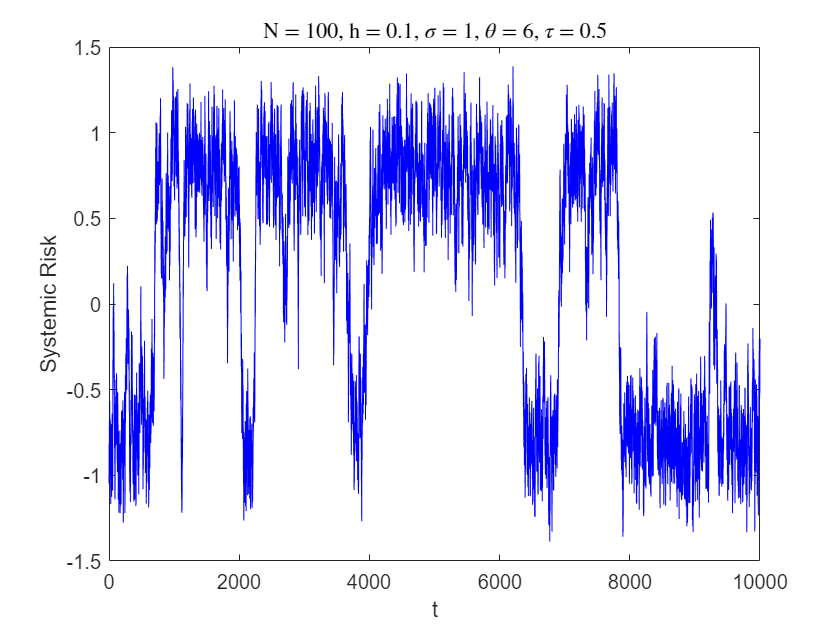

sig = 1;
SolveHomogeneousSDE(t, N, h, sig, theta, 0.5, 0.1, 1);

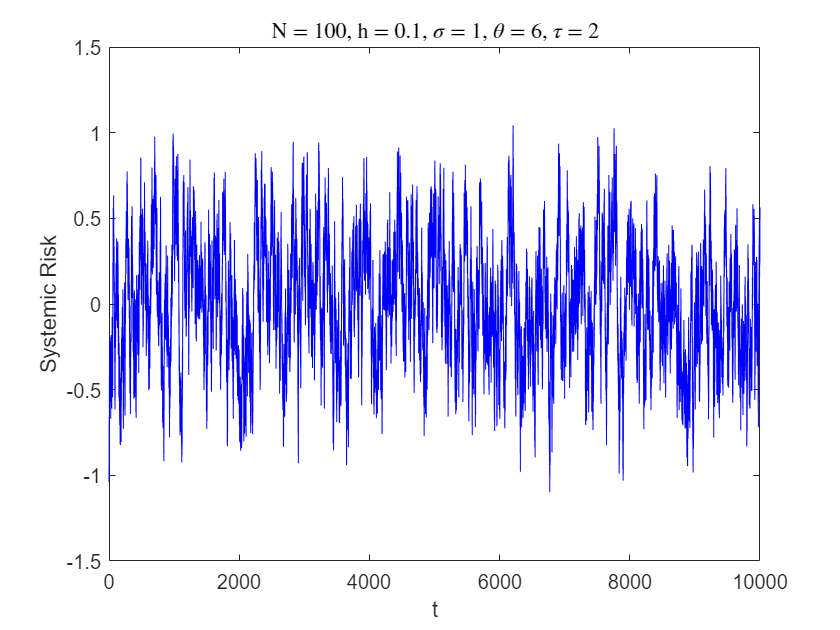

SolveHomogeneousSDE(t, N, h, sig, theta, 2, 0.1, 1);

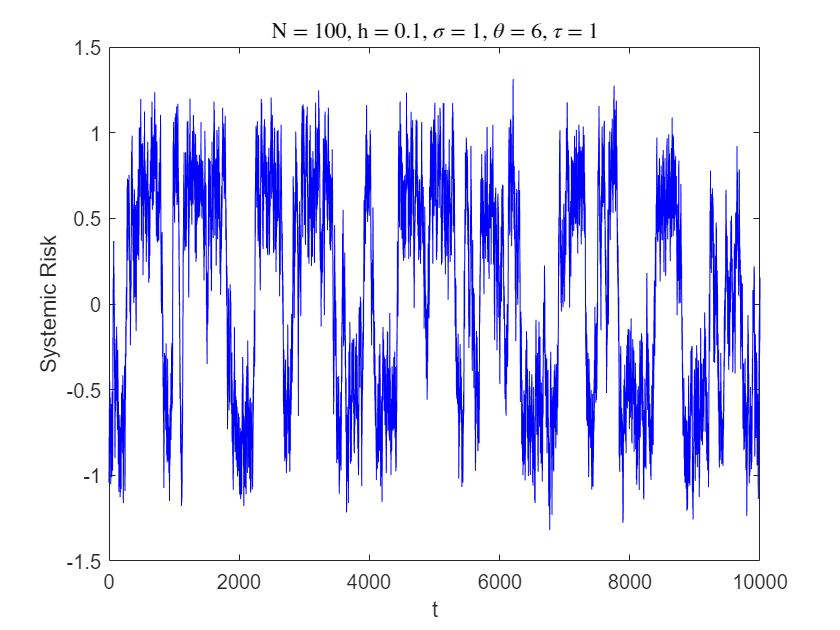

SolveHomogeneousSDE(t, N, h, sig, theta, 1, 0.1, 1);

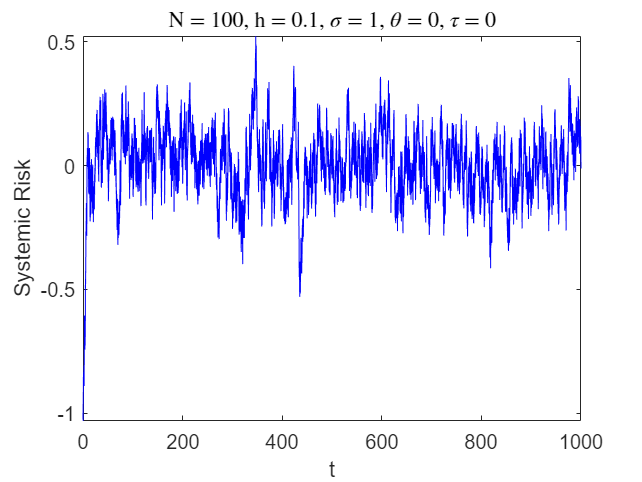

x = SolveHomogeneousSDE(t, N, h, sig, 0, 0, 0, 0);

$\sigma = 1$:

sig = 1;
SolveHomogeneousSDE(t, N, h, sig, theta, tau_low);
SolveHomogeneousSDE(t, N, h, sig, theta, tau_high);

$\sigma = 2$:

sig = 2;
SolveHomogeneousSDE(t, N, h, sig, theta, tau_low);
SolveHomogeneousSDE(t, N, h, sig, theta, tau_high);

$\sigma = 4$:

sig = 4;
SolveHomogeneousSDE(t, N, h, sig, theta, tau_low);
SolveHomogeneousSDE(t, N, h, sig, theta, tau_high);

Thresholding with *heterophily*

compute_f(x) = $\frac{1}{N} \sum_{i = 1}^{N} a_{i,j}\left(x_{i}(t) - x_{j}(t)\right)$

function fvalues = heterophily(x, threshold, a_l, a_h)
    
    % Adjacency matrix
    % Agents interact if the distance between them is below the threshold

    % Compute the pairwise distances between x
    D = pdist2(x, x);
    % The adjacency matrix applies thresholding to the distance matrix
    A = D;
    % Samples that are close together interact weakly
    A(D <= threshold) = a_l;
    % Samples that are far from each other interact as normal
    A(D > threshold) = a_h;

    % Computes f(x) given an adjacency matrix A

    N = length(x);
    fvalues = zeros(N, 1);

    % Compute f(x_{j}) for j = 1,...,N
    for j = 1:N
        fvalues(j) = 1/N .* A(j, :) * (x - x(j));            
    end

end


$$f(t, x) = -h U\left(x_{j}(t)\right) + \theta \left( \frac{1}{N} \sum_{i = 1}^{N} a_{i,j}\left(x_{i}(t) - x_{j}(t)\right) \right)$$


function x = SolveHomogeneousSDE(t, N, h, sig, theta, threshold, a_l, a_h)
    
    % Define SDE
    x0 = -1 + zeros(N, 1);
    U = @(y) y.^3 - y;
    f = @(t, x) -h.*U(x) + theta.* heterophily(x, threshold, a_l, a_h); 
    g = @(t, x) sig;    
   
    % Use Euler-Maruyama to solve SDE
    opts = sdeset('RandSeed', 1);
    x = sde_euler(f, g, t, x0, opts); 
    xbar = mean(x, 2);

    % Plot
    figure; 
    plot(t, xbar, 'b');
    title(['N = ' num2str(N) ',' ...
        ' h = ' num2str(h) ',' ...
        ' $\sigma$ = ' num2str(sig) ',' ...
        ' $\theta$ = ' num2str(theta(:).') ',' ...
        ' $\tau$ = ' num2str(threshold)], ...
    "Interpreter", "latex");
    xlabel('t'); ylabel('Systemic Risk');

end

Heterogeneous agents


$$f(t, x) = -h U\left(x_{j}(t)\right) + \theta_{j} \left( \frac{1}{N} \sum_{i = 1}^{N} a_{i,j}\left(x_{i}(t) - x_{j}(t)\right) \right)$$


function SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, threshold)
    
    % Define SDE
    x0 = -1 + zeros(N, 1);
    U = @(y) y.^3 - y;
    f = @(t, x) -h.*U(x) + theta.*heterophily(x, threshold); 
    g = @(t, x) sig;        

    % Use Euler-Maruyama to solve SDE
    opts = sdeset('RandSeed', 1);
    x = sde_euler(f, g, t, x0, opts);
    xbar = mean(x, 2);  
    
    % Plot
    figure; 
    plot(t, xbar, 'b');
    title(['N = ' num2str(N) ',' ...
        ' h = ' num2str(h) ',' ...
        ' $\sigma$ = ' num2str(sig) ',' ...
        ' $\Theta$ = [' num2str(Theta(:).') '],' ...
        ' $\rho$ = [' num2str(rho(:).') '],' ...
        ' $\tau$ = ' num2str(threshold)], ...
    "Interpreter", "latex");
    xlabel('t'); ylabel('Systemic Risk');
    
end